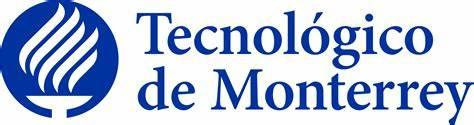

**Actividad 4.**

**Fundamentación de robótica gpo101**

**Hecho por:**

A01736196 | Abraham Ortiz Castro

A01735823 | Ulises Hernandez Hernandez

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*05 de marzo del 2024.*

# *Primer modelo de energía cinética total.*

## *Configuración.*

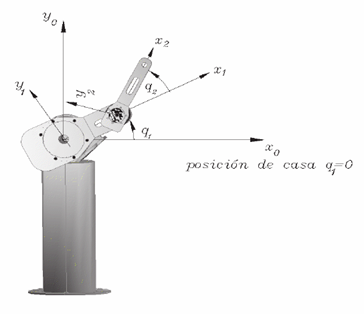

## *Desarrollo.*

%Limpieza de pantalla
clear all
close all
clc

tic

Primero se declaran las variables simbolicas para los dos grados de libertad del robot, se delcaran para los dos angulos, las velocidades y aceleraciones, así como las masas, longitud de los eslabones, distancias y matrices de inercia.

Después se definen los vectores de coordenadas, velocidades y aceleraciones articulares.

%Declaración de variables simbólicas
syms th1(t) th2(t) t  %Angulos de cada articulación
syms th1p(t) th2p(t)    %Velocidades de cada articulación
syms th1pp(t) th2pp(t)     %Aceleraciones de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 %Masas y matrices de Inercia
syms l1 l2 lc1 lc2  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

Se define las dos juntas rotacionales con "0" y se obtiene la dimesión de las columnas del vector para tener el número de grados de libertad.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

En esta sección se definen las matrices de posición y rotación, en este caso no hay transformaciones, por lo que el eje no cambia, como es rotacional, lo giros son sobre Z. En la matriz de posición se escribe el seno y coseno de theta para obtener la posición de la articulación y en la matriz R se pone la matriz de rotación en el eje Z, de la misma manera se llenan las matrices para la articulación dos

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) 0  -sin(th1);
           sin(th1) 0   cos(th1);
           0       -1         0];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    



Se obtienen los jacobianos para la velocidad lineal y angular, así como el calculo de la velocidad lineal y angular de la articulación. Algo muy importante es que el calculo de estas velocidades y los jacobianos pertenecen a la ultima articulación, en este caso como el robot es de dos articulaciones, estas velocidades son de la segunda articulación.

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);


En cuanto a la energía cinética, se crean vectores donde se sutituyen variables para calcular la distancia del origen del eslabon a su centro de masa, de igual manera se crean las matrices de inercia para las dos articulaciones con las variables simbolicas definidas al principio

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón%%%%%%%%%%%%%%%%%%%%%%%%%%%%


En esta parte se calculan los jacobianos y las velocidades para la primera articulación de la misma manera en la que se calculo las de la ultima articulación, solo que en lugar de escribir GDL se pone GDL-1 para hacer referencia al grado de libertad anterior al ultimo, en este caso como solo son 2, GDL-1 es equivalente a la primera articulación.

%Eslabón 1
%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);



A continuación con ayuda de las formulas de la energía cinetica se obtiene la energia en el primer eslabon, primero en V1_Total se obtien la velocidad total sumando la velocidad lineal con el producto cruz de la velocidad angular y la posición, luego en K se utiliza la formula de enegía cinetica con las variables simbolicas de este eslabon. De la misma manera se calcula la energía cinetica del eslabon dos y se suban las energías para obtener la total.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);


%Eslabón 2
V2_Total= V+cross(W,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
%disp('Energía Cinética en el Eslabón 3');
K2= simplify (K2);
%pretty (K3);

K_Total= simplify (K1+K2);
pretty (K_Total);

                                                                                                                      /            2                           2 \
                    __                                                                                                | #1 #9 |lc2|    #1 #5 #8   #2 #4 #3 |l2|  |
                    m2 (lc2 cos(th2(t)) th1p(t) + cos(th1(t)) th1p(t) (l1 + #6) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------- - -------------- |
Izz1 #1   Izz2 #1                                                                                                     \  lc2 th1p(t)      #7        l2 th2p(t)   /
------- + ------- + ----------------------------------------------------------------------------------------------------------------------------------------------
   2         2                                                                             2

                                                                                           

# *Segundo modelo de energía cinética total.*

## *Configuración.*

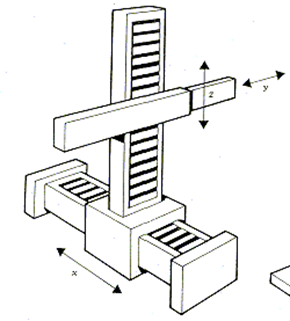

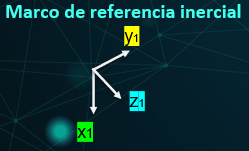


%Limpieza de pantalla
clear all
close all
clc

tic

Se realiza toda la declaración de las vaiables referentes a las articulaciones prismáticas, tanto para la longitud, la velocidad y la aceleración con respecto al tiempo, de misma manera se establecen las masas de cada una de las juntas, así como las matrices de inercia, su longitud y el centro de masa.

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t)  t  %Angulos de cada articulación
syms l1p(t) l2p(t) l3p(t)    %Velocidades de cada articulación
syms l1pp(t) l2pp(t) l3pp(t)    %Aceleraciones de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 %Masas y matrices de Inercia
syms lc1 lc2 lc3  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

Se crean los vectores de coordenadas, velocidades y aceleraciones de los ejes.

%Creamos el vector de coordenadas articulares
Q= [l1; l2; l3];
 
%Creamos el vector de velocidades articulares
Qp= [l1p; l2p; l3p];

%Creamos el vector de aceleraciones articulares
Qpp= [l1pp; l2pp; l3pp];
 
%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Se realizan las traslaciones y rotaciones correspondientes para cada uno de los ejes, esto para que su movimiento corresponda con el eje Z de nuestro marco de referencia, en las transformaciones se realiza primero una rotación de -90° en el eje Y y una rotación de -90° en el eje X.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 respecto a 0....
%Rotación de -90° en y
R(:,:,1)= [0       0        -1;
           0       1         0;
           1       0         0];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0; l2];
%Matriz de rotación de la junta 1 respecto a 0
%Rotación de -90° en x
R(:,:,2)= [1         0         0;
           0         0         1;
           0        -1         0];

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=   [1   0   0;
             0   1   0;
             0   0   1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
   
end



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

## **Metodología Euler-Lagrange**

**Paso 1 y paso 2**

En estos pasos se obtienen la cinemática directa y la cinématica diferencial.


%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
%disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);

**Paso 3**

En este paso es necesario obtener el modelo de energía del sistema, incluyendo la energía cinética que depende de la traslación y rotación del eje, así como de la energía potencial, que depende de la altura, es decir que es importante mantener presente sobre que eje de nuestro marco de referencia se ejerce la fuerza de gravedad. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%

Dado que requerimso conocer la energía cinética es necesario conocer la velocidad de cada uno de los ejes, para esto definimos lasmatrices de inercia de cada uno de los eslabones y definimos tanto la velocidad lineal como la angular de cada uno de los ejes.

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
 P23=subs(P(:,:,3), l3, lc3);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V = V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón

%Eslabón 1

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2));
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2));
% pretty(W2);

%Calculamos la energía cinética para cada uno de los eslabones

Para calcular la velocidad utilizamos la fórmula de energía cinética, que es representada por $\frac{1}{2}{\textrm{mv}}^2$, por lo que obtenemos la velocidad de cada uno de los eslabones, utilizando los jacobianos calculados previamente y expresando la fórmula de energía cinética tomando en cuenta que trabajamos con vectores.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

        2 __
|l1p(t)|  m1
------------
      2





%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

__          2           2
m2 (|l1p(t)|  + |l2p(t)| )
--------------------------
             2





%Eslabón 3
V3_Total= V+cross(W,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W)'*(I3*W);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify (K3);
pretty (K3);

__          2           2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )
--------------------------------------
                   2




K_Total= simplify (K1+K2+K3);
disp("Energía Cinética Total: ")

Energía Cinética Total: 


pretty (K_Total);

__          2           2           2            2 __   __          2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )   |l1p(t)|  m1   m2 (|l1p(t)|  + |l2p(t)| )
-------------------------------------- + ------------ + --------------------------
                   2                           2                     2



Por último desplegamos la energía cnética de cada uno de los eslabones, así como la suma de energías cinéticas, podemos observar que la energía cinética depende de su masa (m1) y y de la velocidad de su eslabon (l1). De igual manera vemos como la energía cinética del eslabón 2 depende de la velocidad de tanto l1 como de l2 y su masa (m2), y como se puede intuir para este momento, la energía cinética del tercer eslabón depende de la velocidad de tanto l1, l2 y l3 y de su masa (m3). Por último la energía total resulta de sumar la energía cinética de cada uno de los eslabones. 


%Calculamos la energía potencial para cada uno de los eslabones
%Obtenemos las alturas respecto a la gravedad
 h1= P01(1); %Tomo la altura paralela al eje z
 h2= P12(3); %Tomo la altura paralela al eje y
 h3= P23(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1;
 U2=m2*g*h2;
 U3=m3*g*h3;

 %Calculamos la energía potencial total
 U_Total= U1 + U2 +U3;

 %Obtenemos el Lagrangiano
 %disp('Lagrangiano: ');
 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

%Modelo de Energía
 %disp('Modelo de energía: ');
 H= simplify (K_Total+U_Total);
 %pretty (H)